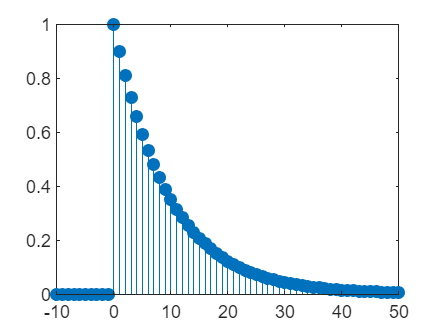

clc;
clear all;

t = -10:50;

for n = 11:61
    u(1,n) = heaviside(n);
    Xn(1,n) = u(1,n) - u(n-10);
    hn(1,n) = (0.9)^(n-11)*u(1,n);
end
stem(t,hn,'filled');
xlim([-10,50]);   
ylim([0,1]);

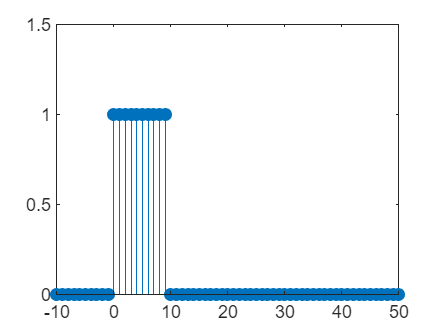

stem(t,Xn,'filled');
xlim([-10,50]);
ylim([0,1.5]);

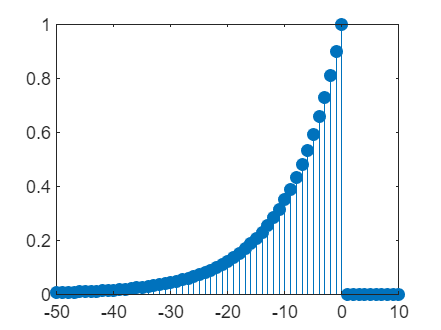

%set h[k] => h[-k]
for n = 11:71
    hn_refelct(1,n-10) = hn(1,72-n);
end
t = -50:10;
stem(t,hn_refelct,'filled');
xlim([-50,10]);

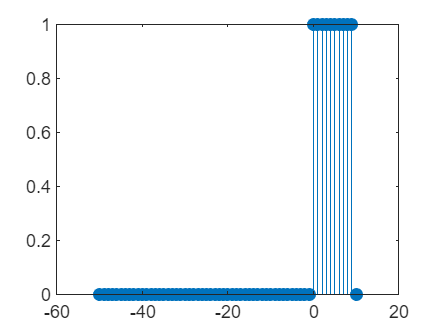

Xn_shift = circshift(Xn,40);
stem(t,Xn_shift,'filled');

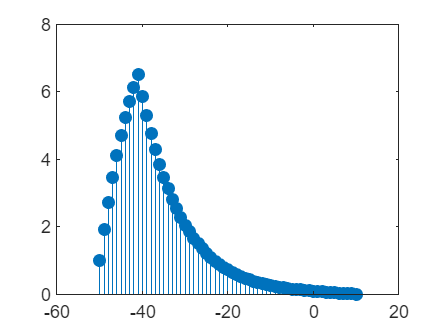

for k = 1:61
    for n = 1:61
        yn(1,n) = Xn_shift(62-n)*hn_refelct(62-n);
    end
    yn_sum(1,k) = sum(yn);
    Xn_shift = circshift(Xn_shift,-1);
end
stem(t,yn_sum,'filled');

% yn(1,k+10) = Xn(k+10)*hn_refelct(-k+52);

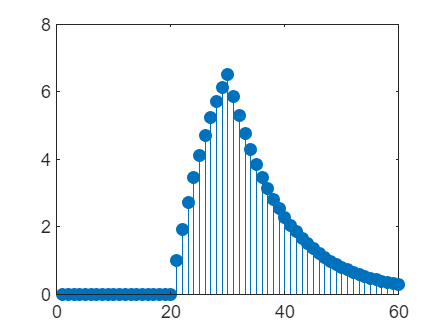

%set convution

W = conv(hn,Xn);
stem(W,'filled');
xlim([0,60]);